# Core Layer

Each node only connects to Internet in upper layer

nodes of core layer as input argument

core=3;
endnodes = cell(core+1, 1);
endnodes{1}='IT'

endnodes = 4×1 cell array
    'IT'
    []
    []
    []


for i=1:core
    endnodes{i+1} = strcat('C', num2str(i));
end
NodeTable=table(endnodes,'VariableNames',{'EndNodes'})

NodeTable = 4×1 table
    EndNodes
    ________

    'IT'    
    'C1'    
    'C2'    
    'C3'    


%edges=zeros(nodes+1)
%for i=1:nodes
 %   edges(1,i+1)=1
  %  edges(i+1,1)=1
%end
edges=[];
for i=1:core
    edges=[edges; 1 i+1];
end
EdgeTable=table(edges,'VariableNames',{'EndNodes'})

EdgeTable = 3×1 table
    EndNodes
    ________

    1    2  
    1    3  
    1    4  


G=graph(EdgeTable,NodeTable);

## plot core layer

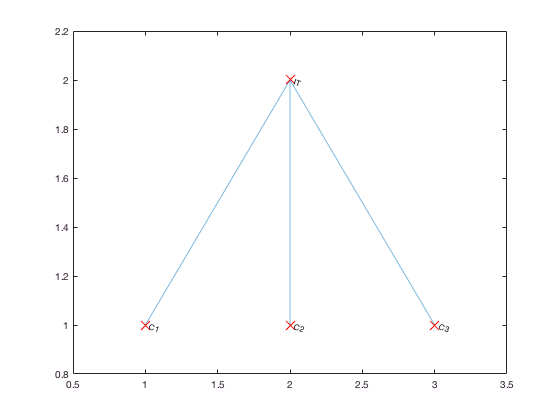

p = plot(G,'NodeLabel',table2cell(G.Nodes));
p.Marker = 'x';
p.NodeColor = 'r';
p.MarkerSize = 10;

XDatacore = p.XData;
YDatacore = p.YData;

# Aggregation layer

Each node connects to all nodes in core layer

aggregation=6;
%endnodes = cell(aggregation, 1);
for i=1:aggregation
    endnodes{i+core+1} = strcat('A', num2str(i));
end
NodeTable=table(endnodes,'VariableNames',{'EndNodes'})

NodeTable = 10×1 table
    EndNodes
    ________

    'IT'    
    'C1'    
    'C2'    
    'C3'    
    'A1'    
    'A2'    
    'A3'    
    'A4'    
    'A5'    
    'A6'    


%edges=zeros(nodes+1)
%for i=1:nodes
 %   edges(1,i+1)=1
  %  edges(i+1,1)=1
%end
%aggedges=[];
for i=1:aggregation
    for j=2:core+1
    edges=[edges; core+1+i j];
    end
end
EdgeTable=table(edges,'VariableNames',{'EndNodes'})

EdgeTable = 21×1 table
    EndNodes
    ________

     1     2
     1     3
     1     4
     5     2
     5     3
     5     4
     6     2
     6     3
     6     4
     7     2
     7     3
     7     4
     8     2
     8     3
     8     4
     9     2
     9     3
     9     4
    10     2
    10     3
    10     4


%G=addedge(G,EdgeTable);
G=graph(EdgeTable,NodeTable);

## plot aggregation layer

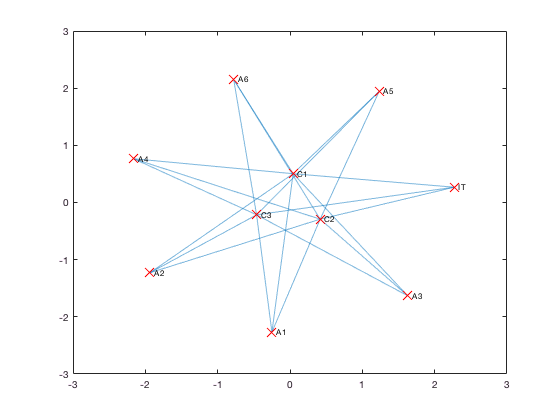

p = plot(G,'NodeLabel',table2cell(G.Nodes));
p.Marker = 'x';
p.NodeColor = 'r';
p.MarkerSize = 10;

## Change coordinates to better look

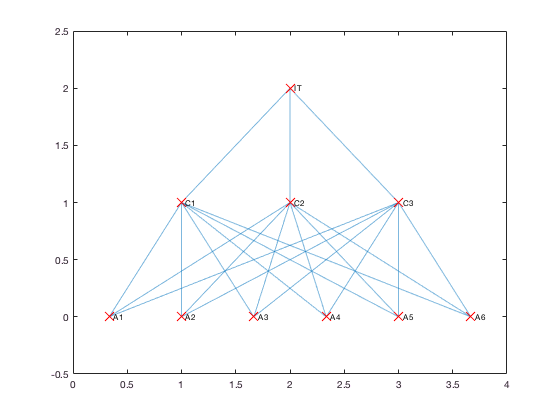

XDataaggr = XDatacore;
YDataaggr = YDatacore;

start=YDatacore(1,2);
difference=YDatacore(1,2)-YDatacore(1,1);
for i=1:aggregation
    YDataaggr=[YDataaggr, start+difference];
end

differenceag=(XDatacore(1,end)+1)/aggregation;
start=differenceag/2;
for i=0:aggregation-1
    XDataaggr=[XDataaggr, start+differenceag*i];
end

p.XData = XDataaggr;
p.YData = YDataaggr;

# Symmetric Edge layer

Each node connects to only one node in aggregation layer. Since taken symmetric, each node in aggregation layer has the same number of edge nodes.

edgesl=3; %That each node in aggregation layer has
%endnodes = cell(aggregation, 1);
count=1;
for i=1:edgesl
    for j=1:aggregation
    endnodes{core+aggregation+count+1} = strcat('E', num2str(count));
    count=count+1;
    end
end
NodeTable=table(endnodes,'VariableNames',{'EndNodes'})

NodeTable = 28×1 table
    EndNodes
    ________

    'IT'    
    'C1'    
    'C2'    
    'C3'    
    'A1'    
    'A2'    
    'A3'    
    'A4'    
    'A5'    
    'A6'    
    'E1'    
    'E2'    
    'E3'    
    'E4'    
    'E5'    
    'E6'    
    'E7'    
    'E8'    
    'E9'    
    'E10'   
    'E11'   
    'E12'   
    'E13'   
    'E14'   
    'E15'   
    'E16'   
    'E17'   
    'E18'   


count=1;
for j=1:aggregation
    for i=1:edgesl
        edges=[edges; core+1+j core+aggregation+1+i+(count-1)*edgesl];
    end
    count=count+1;
end
EdgeTable=table(edges,'VariableNames',{'EndNodes'})

EdgeTable = 39×1 table
    EndNodes
    ________

     1     2
     1     3
     1     4
     5     2
     5     3
     5     4
     6     2
     6     3
     6     4
     7     2
     7     3
     7     4
     8     2
     8     3
     8     4
     9     2
     9     3
     9     4
    10     2
    10     3
    10     4
     5    11
     5    12
     5    13
     6    14
     6    15
     6    16
     7    17
     7    18
     7    19
     8    20
     8    21
     8    22
     9    23
     9    24
     9    25
    10    26
    10    27
    10    28


G=graph(EdgeTable,NodeTable);

## plot aggregation layer

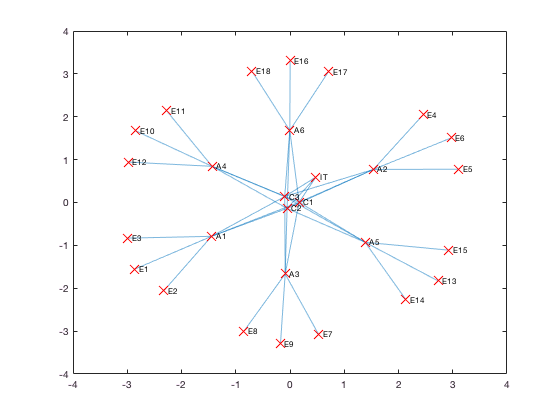

p = plot(G,'NodeLabel',table2cell(G.Nodes));
p.Marker = 'x';
p.NodeColor = 'r';
p.MarkerSize = 10;

## Change coordinates to better look

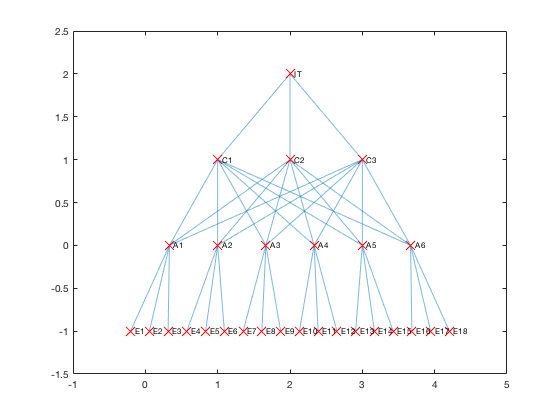

XDatedge = XDataaggr;
YDatedge = YDataaggr;

start=YDatedge(1,end);
difference=YDatedge(1,end)-YDatedge(1,end-aggregation);
for i=1:edgesl*aggregation
    YDatedge=[YDatedge, start+difference];
end

difference=(XDatedge(1,end)+1)/(edgesl*aggregation);
start=(differenceag*aggregation-(difference*(edgesl*aggregation-1)))/2;
for i=0:edgesl*aggregation-1
    XDatedge=[XDatedge, start+difference*i];
end

p.XData = XDatedge;
p.YData = YDatedge;